fft_size = 128;
line = 1:fft_size;


s1 = cos(line*0.1)' ;%+ rand(fft_size,1)*0.2;
s2 = delayseq(s1, 14)*0.4;% +  delayseq(s1, 29);
s1 = s1(1:fft_size) + rand(fft_size, 1)*0.2;
s2 = s2(1:fft_size) + rand(fft_size, 1)*0.2;


s1 = s1 - sum(s1)/size(s1,1);
s1 = s1./(sum(abs(s1))./size(s1, 1));
s2 = s2 - sum(s2)/size(s2,1);
s2 = s2./(sum(abs(s2))./size(s2, 1));

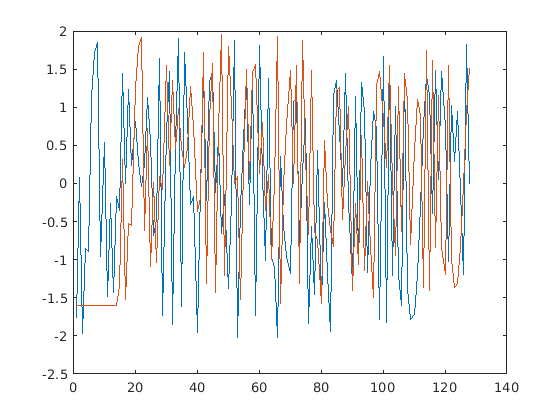


plot(s1)
hold on;
plot(s2)
hold off;

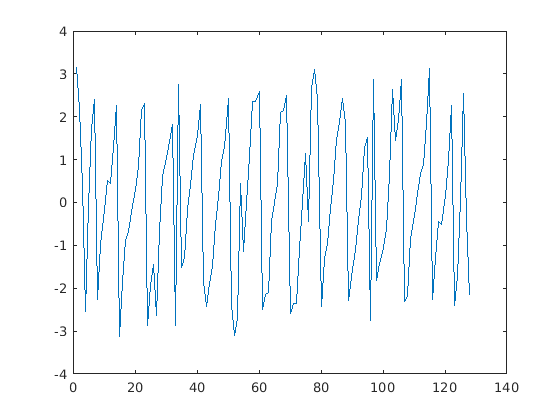


fs1 = fft(s1, fft_size);
fs2 = fft(s2, fft_size);
fs12 = fs2.*conj(fs1);


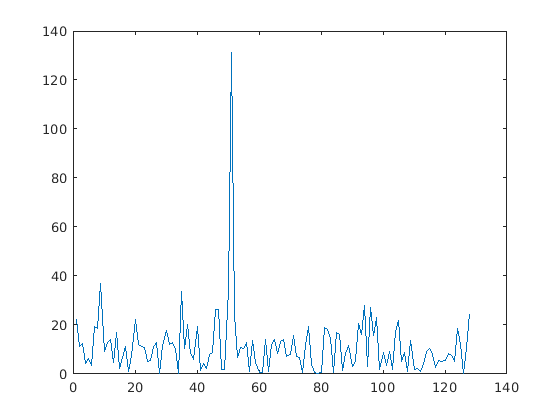

plot(abs(fftshift(ifft(fs12./abs(fs12)), 1)))


[~, n] = max(abs(fftshift(ifft(fs12./abs(fs12)), 1)));
n = n - fft_size/2 - 1

n = 115

[gccphat_res,r12] = gccphat(s2,s1);
gccphat_res

gccphat_res = 14

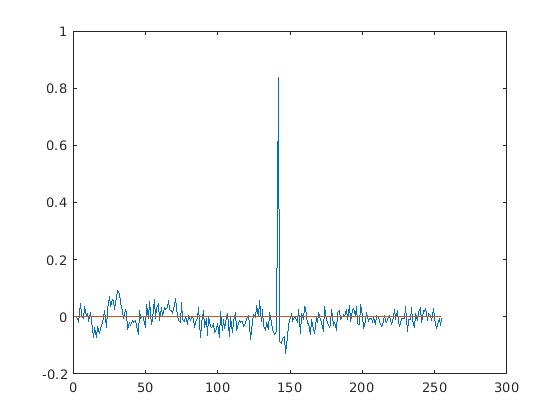

plot(1:255,real(r12),1:255,imag(r12))